clear all
clc
%set variables
Model.Nx=2000;                      % number of grid points in the x (row) direction
Model.Ny=1024;                       % number of grid points in the y (column) direction
Model.dx= 3.75e-05;                % grid point spacing in the x direction [m]
Model.dy= 3.75e-05;                % grid point spacing in the y direction [m]
Model.sample_rate_model=1e9/5;        %[HZ]
Model.sample_rate_exp=1e9/5;          %[HZ]
Model.amplitude=0.01;
Medium.speed_of_sound=1480; %speed of sound in a homogeneous medium should be the same as the model[m/s]
Medium.sound_speed_sample=1480;%speed of sound inside the sample
Medium.density_sample=997;%density of the sample
Medium.absorption=245;               %[1/m]
Geometry.l=0.019;                    %diameter of transducer
Geometry.sensor_thikness=3.75e-05; %thikness of the sensor
Geometry.distance=0.02439;%distance between the back of cuvette and transducer[m].
Geometry.cuvette_length=0.0055;%Width of the sample inside the cuvette
Geometry.cuvette_face=5e-3;   %thickness of PMMA layer
Geometry.cuvette_Gasket=0.5e-3   % thickness of silicon rubber
Geometry.cuvette_diameter=0.018; % diameter of the sample inside the cylindrical cuvette.[m]
Geometry.a=1.16;


%read experimental data from TDMS files
filename = 'C:\Users\Marzieh\Documents\Marzieh\Data\18.07.2023\CUSO40.25M.18.7.2023_blue_ND0.6_test3_20230718_120943_276.tdms';
my_tdms_struct = TDMS_getStruct(filename,1);
channels=my_tdms_struct.M680D0;
S_exp=Mean_Tdms(channels);
figure(20)
plot(0:1/Model.sample_rate_exp*Medium.speed_of_sound:(length(S_exp)-1)*Medium.speed_of_sound/Model.sample_rate_exp,S_exp/max(S_exp(:)))
%S_exp=smoothdata(S_exp,'movmean',50);


global source;
global sensor_data;
global sensor;
global medium;
S_model=forward_homogeneous(Model, Medium, Geometry);
%Run the forward model to get simulated data.
medium_m=medium;
sensor_m=sensor;
source_m=source;
data_m=sensor_data;
%signal_m=S_model;


[S_model_processed, S_exp_processed] =processsignals_alternative(S_model,S_exp, Model, Medium, Geometry);
%process both experimental and simulated data to compare them. 
%steps of the process:
%1_ match sample rates of experimental and simulated data.
%3_ correct offset of experimental signal.
%4_ match time delays of experimental and simulated signals
%5_ normalizing simulated data based on experimental data.


%Error calculation
global X_exp_pos
global X_model_pos
global Y_exp_pos
global Y_model_pos

RMSE_total=sqrt(mean((S_exp_processed-S_model_processed).^2))/sqrt(mean((S_exp_processed).^2))*100;
RMSE_pos=sqrt(mean((Y_exp_pos-Y_model_pos).^2))/sqrt(mean((Y_exp_pos).^2))*100;
peak_to_peak_amplitude=abs(min(S_exp_processed(:))-min(S_model_processed(:)))/abs(min(S_exp_processed(:)))*100;


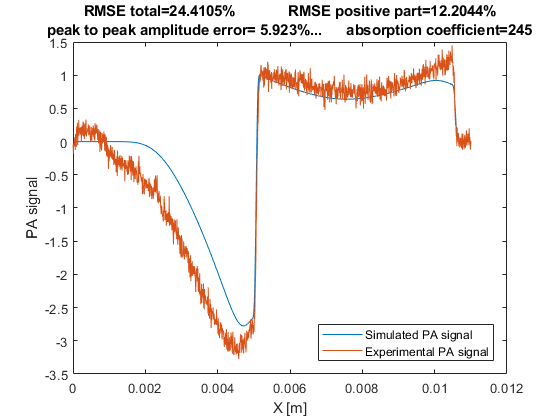


%visualizatoin
global X_exp
global X_model
global p_0

figure(11)
plot(X_model, S_model_processed);
hold on
plot(X_exp, S_exp_processed/0.8);

ylabel('PA signal');
xlabel('X [m]');
title({['RMSE total=',num2str(RMSE_total),'%             RMSE positive part=',num2str(RMSE_pos),'%'],...
    ['peak to peak amplitude error= ',num2str(peak_to_peak_amplitude),'%...' ...
    '      absorption coefficient=',num2str(Medium.absorption)]});

legend('Simulated PA signal','Experimental PA signal', 'Location','southeast')

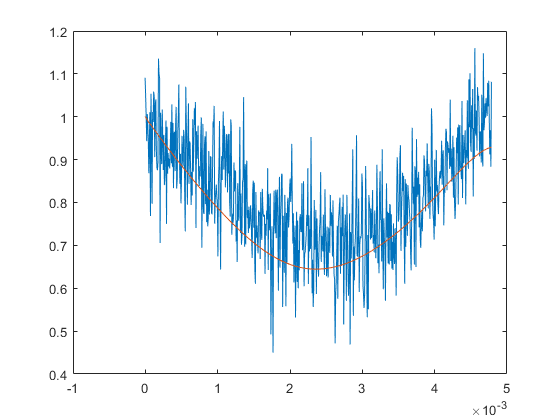


figure(10)
plot(X_exp_pos,Y_exp_pos)
hold on
plot(X_model_pos,Y_model_pos)

%plot(X_exp_pos,fitresult(X_exp_pos))
%plot(X_model_pos,fitresultm(X_model_pos))
%title({['absorption coefficient fitted exp=',num2str(coeffvals(1,2))],...
   % ['absorption coefficient fitted model=',num2str(coeffvalsm(1,2))]})
%legend('experimental data','simulated data', 'experimental fit', 'simulated fit')

